Carico la shape:

M = load_off('c:/users/rodola/workspace/data/tosca/dog5.off');
M = remesh(M, struct('vertices',5e3));

Calcolo le normali per ogni triangolo:

normals = cross(...
    M.VERT(M.TRIV(:,2),:)-M.VERT(M.TRIV(:,1),:),...
    M.VERT(M.TRIV(:,3),:)-M.VERT(M.TRIV(:,1),:));
normals = spdiag(1./sqrt(sum(normals.^2,2)))*normals;

Calcolo le normali per ogni vertice usando l'adiacenza vertice-triangolo:

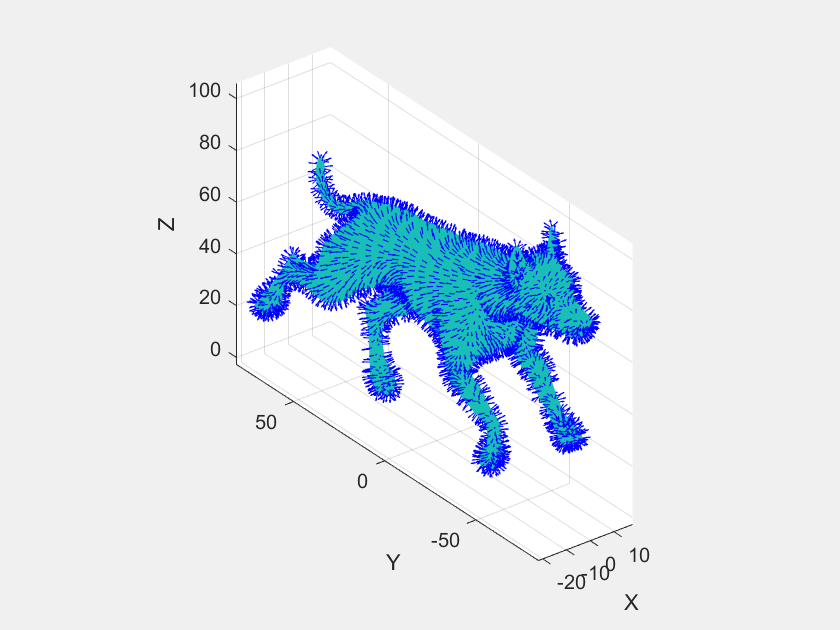

P = sparse(M.TRIV(:), [1:M.m, 1:M.m, 1:M.m], 1, M.n, M.m);
normals_v = P*normals;
normals_v = spdiag(1./sqrt(sum(normals_v.^2,2)))*normals_v;

figure
plot_mesh(M), hold on; shading interp
plot_vfield(M.VERT, normals_v, 1)

Gonfiamo il cane:

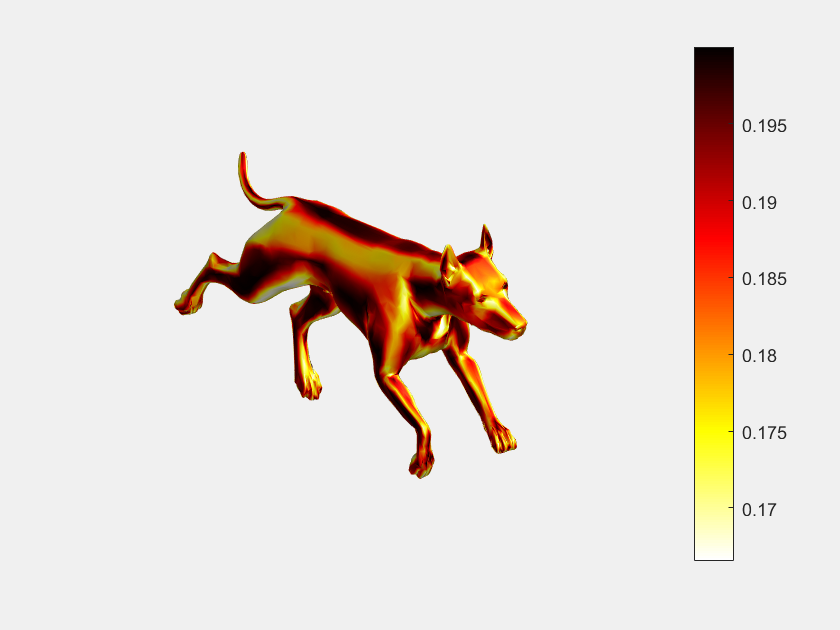

colors = hot(200);
colors = colors(end:-1:1,:);
figure, colormap(colors)
for a=0:0.005:0.25
    N = M;
    N.VERT = N.VERT + a*normals_v;
    err = sum(abs(N.VERT-M.VERT).^3,2).^(1/3);
    plot_scalar_map(M, err);
    light; lighting phong; camlight head; axis off
    colorbar
    drawnow
end

Calcoliamo l'errore pointwise:

N = M;
N.VERT = N.VERT + 0.2*normals_v;

err = sum(abs(N.VERT-M.VERT).^3,2).^(1/3);

figure, colormap(hot)
plot_scalar_map(M, err)

ans =   Patch with properties:

    FaceColor: 'interp'
    FaceAlpha: 1
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [9963×3 double]
     Vertices: [5000×3 double]

  Show all properties


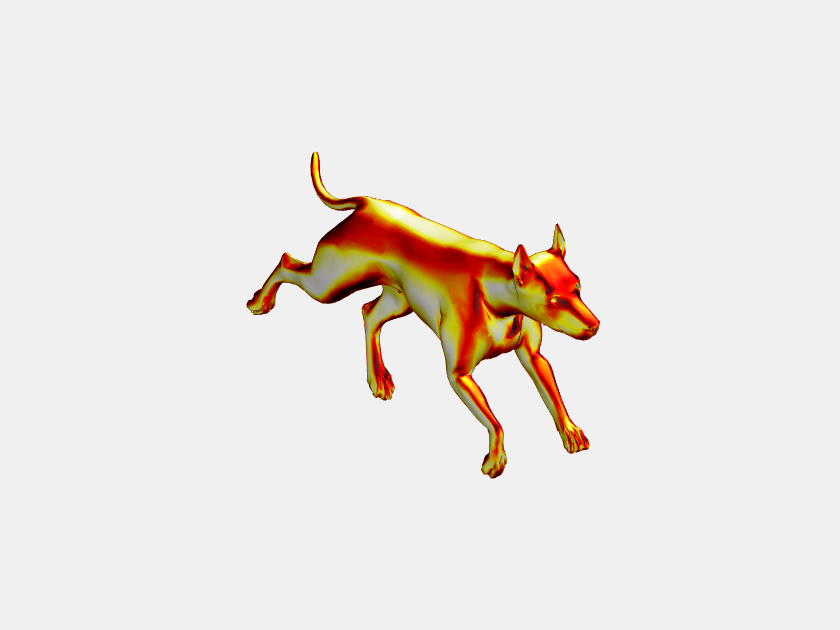

light; lighting phong; camlight head; axis off